# Presentación final: ejercicio 1

En esta actividad final se obtiene la matriz de transformación T empleando variables simbólicas y de esta manera obtener la cinemática diferencial con la velocidad lineal y angular. El sistema que se analizará es el siguiente:

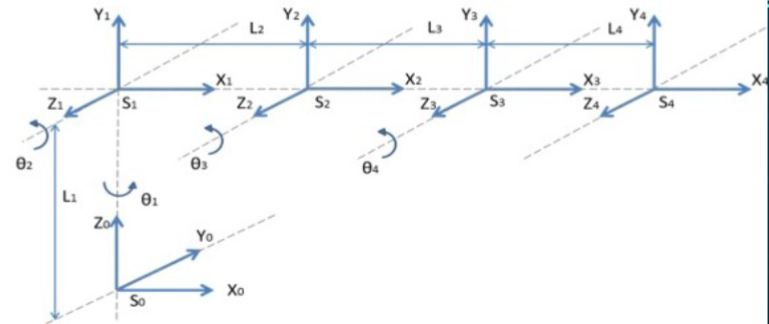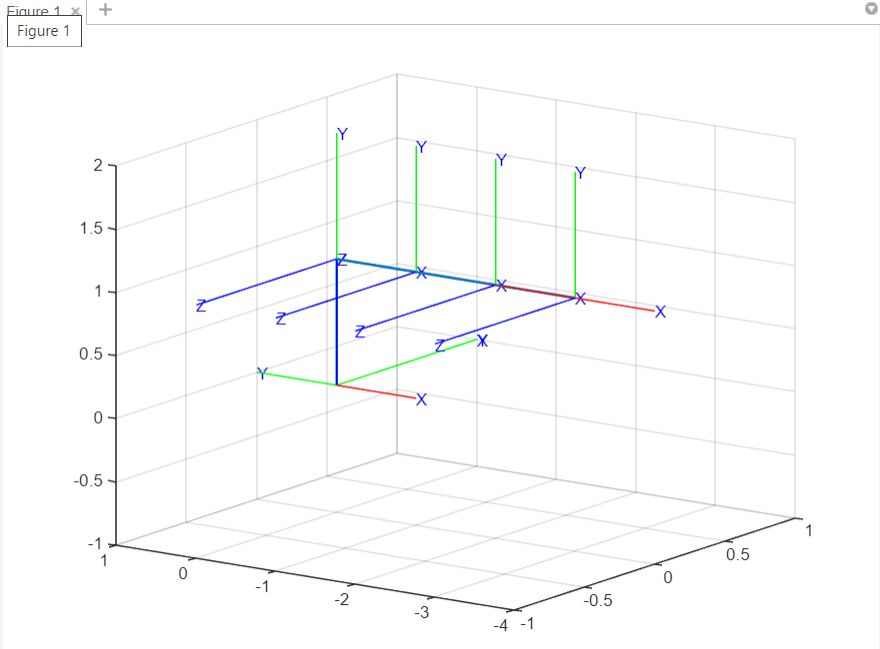

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) th5(t) t a0 a1 a2 a3 a4

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0 0 0];

%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3, th4, th5];
%disp('Coordenadas generalizadas');
pretty (Q);

(th1(t), th2(t), th3(t), th4(t), th5(t))




%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
pretty (Qp);

/  d          d          d          d          d        \
| -- th1(t), -- th2(t), -- th3(t), -- th4(t), -- th5(t) |
\ dt         dt         dt         dt         dt        /



%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%H1
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [a0;a0;a0];
%Matriz de rotación en z de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];


%H2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0 ;0 ; a1];
%Matriz de rotación en x de la junta 1 respecto a 0
R(:,:,2)= [1  0  0;
           0 cos(th2)  -sin(th2);
           0 sin(th2)   cos(th2)];


%H3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [a2; 0;0];
%Matriz sin rotación
R(:,:,3)=   [1 0 0;
             0 1 0;
             0 0 1];

%H4 
%Posición de la articulación
P(:,:,4)= [a3; 0;0];
%Matriz sin rotación
R(:,:,4)=   [1 0 0;
             0 1 0;
             0 0 1];

%H5 
%Posición de la articulación
P(:,:,5)= [a4; 0;0];
%Matriz sin rotación
R(:,:,5)=   [1 0 0;
             0 1 0;
             0 0 1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de
% referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, a0 \
|                                  |
| sin(th1(t)),  cos(th1(t)), 0, a0 |
|                                  |
|      0,            0,      1, a0 |
|                                  |
\      0,            0,      0,  1 /



Matriz de Transformación global T2


/ cos(th1(t)), -cos(th2(t)) sin(th1(t)),  sin(th1(t)) sin(th2(t)),    a0   \
|                                                                          |
| sin(th1(t)),  cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)),    a0   |
|                                                                          |
|      0,             sin(th2(t)),              cos(th2(t)),       a0 + a1 |
|                                                                          |
\      0,                  0,                        0,               1    /



Matriz de Transformación global T3


/ cos(th1(t)), -cos(th2(t)) sin(th1(t)),  sin(th1(t)) sin(th2(t)), a0 + a2 cos(th1(t)) \
|                                                                                      |
| sin(th1(t)),  cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)), a0 + a2 sin(th1(t)) |
|                                                                                      |
|      0,             sin(th2(t)),              cos(th2(t)),             a0 + a1       |
|                                                                                      |
\      0,                  0,                        0,                     1          /



Matriz de Transformación global T4


/ cos(th1(t)), -cos(th2(t)) sin(th1(t)),  sin(th1(t)) sin(th2(t)), a0 + a2 cos(th1(t)) + a3 cos(th1(t)) \
|                                                                                                       |
| sin(th1(t)),  cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)), a0 + a2 sin(th1(t)) + a3 sin(th1(t)) |
|                                                                                                       |
|      0,             sin(th2(t)),              cos(th2(t)),                      a0 + a1               |
|                                                                                                       |
\      0,                  0,                        0,                              1                  /



Matriz de Transformación global T5


/ cos(th1(t)), -cos(th2(t)) sin(th1(t)),  sin(th1(t)) sin(th2(t)), a0 + a2 cos(th1(t)) + a3 cos(th1(t)) + a4 cos(th1(t)) \
|                                                                                                                        |
| sin(th1(t)),  cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)), a0 + a2 sin(th1(t)) + a3 sin(th1(t)) + a4 sin(th1(t)) |
|                                                                                                                        |
|      0,             sin(th2(t)),              cos(th2(t)),                              a0 + a1                        |
|                                                                                                                        |
\      0,                  0,                        0,                                      1                           /





% %Calculamos el jacobiano lineal de forma diferencial
% %disp('Jacobiano lineal obtenido de forma diferencial');
% %Derivadas parciales de x respecto a th1 y th2
% Jv11= functionalDerivative(PO(1,1,GDL), th1);
% Jv12= functionalDerivative(PO(1,1,GDL), th2);
% Jv13= functionalDerivative(PO(1,1,GDL), th3);
% %Derivadas parciales de y respecto a th1 y th2
% Jv21= functionalDerivative(PO(2,1,GDL), th1);
% Jv22= functionalDerivative(PO(2,1,GDL), th2);
% Jv23= functionalDerivative(PO(2,1,GDL), th3);
% %Derivadas parciales de z respecto a th1 y th2
% Jv31= functionalDerivative(PO(3,1,GDL), th1);
% Jv32= functionalDerivative(PO(3,1,GDL), th2);
% Jv33= functionalDerivative(PO(3,1,GDL), th3);

% %Creamos la matríz del Jacobiano lineal
% jv_d=simplify([Jv11 Jv12 Jv13;
%               Jv21 Jv22 Jv23;
%               Jv31 Jv32 Jv33]);
% %pretty(jv_d);


%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 
            % con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene
            % la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

[[- #5 (a0 + a2 sin(th1(t)) + a3 sin(th1(t)) + a4 sin(th1(t))) - #4 sin(th1(t)) (a2 + a3 + a4) - #2 cos(th2(t)) sin(th1(t)) (a3 + a4)

   - a4 #1 cos(th2(t)) sin(th1(t)) - #3 cos(th2(t)) sin(th1(t)) (a2 + a3 + a4)],

  [#5 (a0 + a2 cos(th1(t)) + a3 cos(th1(t)) + a4 cos(th1(t))) + #4 cos(th1(t)) (a2 + a3 + a4) + #2 cos(th1(t)) cos(th2(t)) (a3 + a4)

   + a4 #1 cos(th1(t)) cos(th2(t)) + #3 cos(th1(t)) cos(th2(t)) (a2 + a3 + a4)],

  [#2 sin(th2(t)) (a3 + a4) + a4 #1 sin(th2(t)) + #3 sin(th2(t)) (a2 + a3 + a4)]]

where

         _________
          d
   #1 == -- th5(t)
         dt

         _________
          d
   #2 == -- th4(t)
         dt

         _________
          d
   #3 == -- th3(t)
         dt

         _________
          d
   #4 == -- th2(t)
         dt

         _________
          d
   #5 == -- th1(t)
         dt




disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
    pretty(W);

/                  sin(th1(t)) sin(th2(t)) (#3 + #2 + #1)                  \
|                                                                          |
|                  -cos(th1(t)) sin(th2(t)) (#3 + #2 + #1)                 |
|                                                                          |
| _________   _________                                                    |
|  d           d                                                           |
| -- th1(t) + -- th2(t) + #3 cos(th2(t)) + #2 cos(th2(t)) + #1 cos(th2(t)) |
\ dt          dt                                                           /

where

         _________
          d
   #1 == -- th5(t)
         dt

         _________
          d
   #2 == -- th4(t)
         dt

         _________
          d
   #3 == -- th3(t)
         dt


